# SpeakEasy 2: Champagne

SpeakEasy2 is used to detect community structure in graphs. To generate a sample graph, the `preference` random game from the `matlab-igraph` toolbox can be used. This will create a graph with "blocks" (or communities) or different sizes.

blockSizes = [10 10 10 10 20 20 30];

The above `blockSizes` vector describes the size of 7 communities, the total number of nodes in the graph will be `sum(blockSizes)`. The distribution of community sizes vaguely follows a discrete power law distribution, where the smallest community size occurs must frequently, the next largest community size is twice as large and occurs have as often, then the next size is three times as large and occurs a third as often as the smallest, and so on.

igraph.rng(9999); % Set igraph's RNG seed.
g = igraph.randgame('preference', blockSizes=blockSizes, mixingParam=0.2);
g = (g + g') > 0; % Make symmetric.

The mixing parameter provides the liklihood an edge is between two nodes in different communities (i.e. the proportion of edges mixing communities).

To cluster the graph use:

[memb, ordering] = speakeasy2(g, seed=1234);

The `ordering` output is optional but is useful for ploting with the `imagesc` command. The `seed` argument provides a random seed to allow for reproducible results.

Clustering can be viewed use `igraph.plot` or `imagesc`. While `igraph.plot` can provide a clearer view of the network, as networks get large, it can get too crowded.

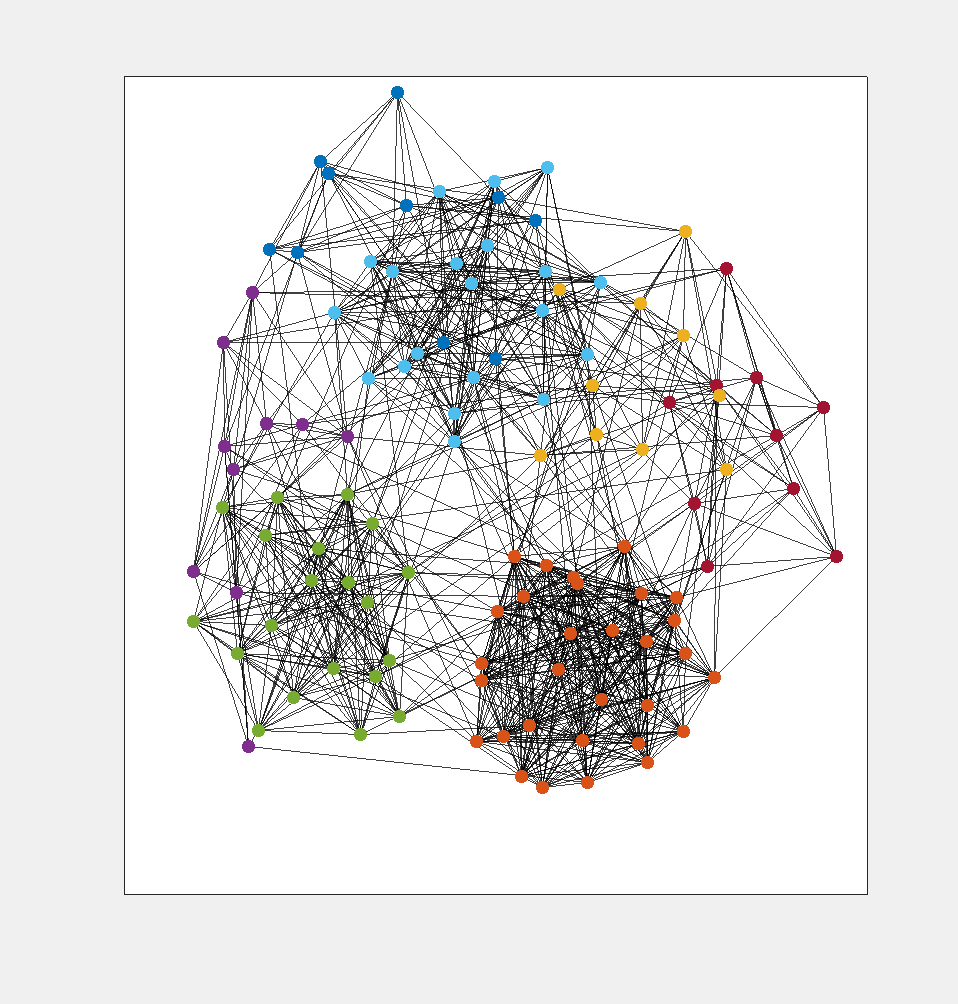

igraph.plot(g, 'kk', membership=memb);

In the above plot, the Kamada-Kawai layout didn't do a great job at picking up the smaller communities so it looks like communities are mixed together.

For `imagsc`, the ordering vector is used to index the adjacency matrix so nodes in the same cluster are near each other, with communities sorted in descending order by size, such that the largest communities end up near the top-left.

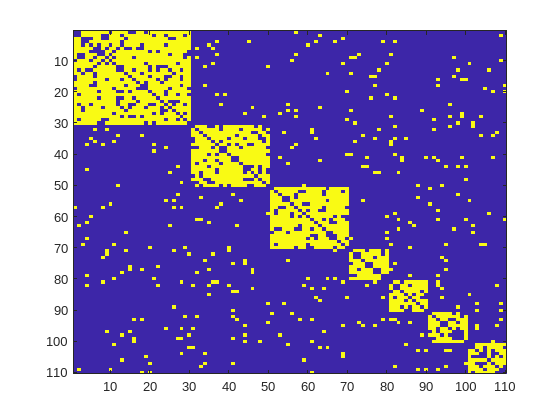

imagesc(g(ordering,ordering)); 

Clusters stand out clearer in the `imagesc` figure. All 7 of the original communities can be picked out, even if the smallest communites are less well defined.

## Arguments

SpeakEasy2 has several optional arguments to tweak how the algorithm runs but most shouldn't need to be changed without good reason. The arguments that are likely to be useful are: `maxThreads`, `seed`, and `verbose`. Use `maxThreads` to modify the number of processing cores SpeakEasy2 can use. By default, the decision is left to `OpenMP, meaning it will use all available processing cores or the number provided by the OMP_NUM_THREADS `environment variable, if that is set. To turn off parallel processing, set `maxThreads` to `1`. 

The random seed can be set using the `seed` option. This changes the RNG used by SpeakEasy2, which is different than the RNG used by MATLAB and functions from the `matlab-igraph` toolbox. As such, strange results or correlations may occur if multiple RNG are set to use the same seed. The seed allows reproducible results. By default, the seed is set to a random number using MATLAB's RNG. Because of this, if you want to run SpeakEasy2 on multiple graphs and have the results all be reproducible, you can set MATLAB's RNG and leave the `seed` option unset.

To get more information about the clustering process, you can set the `verbose` option to `true`. This will cause SpeakEasy2 to print various stats about the graph and process. Due to the way MATLAB matrices are converted to C data types, SpeakEasy2 will always claim graphs are weighted. This behavior may change in the future.